f=@(x) 2.^x;
df = derivate(f);
ddf= derivate(df);
xx=-1:0.01:2;
P = [-1,0,0.5,1,2];
plot(xx, f(xx), P, f(P), "r*");
hold on
n = length(P) - 1;
Pol = polyfit(P, f(P), n);
Pol_d = polyder(Pol);
Pol_dd = polyder(Pol_d);
plot(xx, polyval(Pol, xx));
plot(xx, polyval(Pol_d, xx));
plot(xx, polyval(Pol_dd, xx));
disp("Real value of second derivative in x = 0")

Real value of second derivative in x = 0


f__ = ddf(0)

f__ =    0.480453013918201


disp("Value in x = 0 of interpolation polynomial diferentiated 2x")

Value in x = 0 of interpolation polynomial diferentiated 2x


P__f = polyval(Pol_dd, 0)

P__f =    0.471685111562328


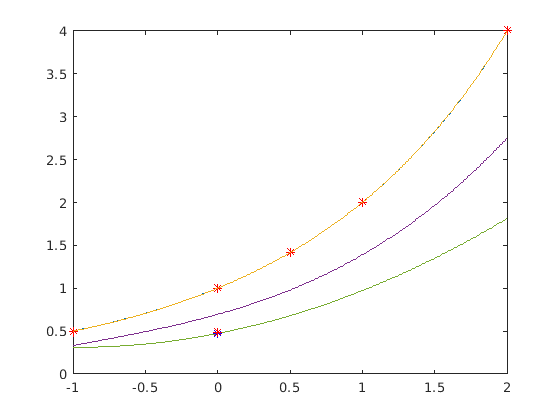

plot(0,P__f, "b*" ,0, f__, "r*")
hold off